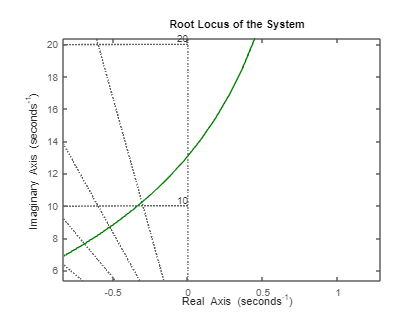

clear 
clc 

% Define the constants
k0 = 1.3;
b = 12;
a1 = 3;
a2 = 5;
a3 = 2;

% Define the numerator and denominator of the transfer function
num = k0 * [1 b];
den = conv(conv([1 a1], [1 a2]), [1 a3]);

% Create the transfer function
G = tf(num, den);


% Initialize the range of Kp values for trial and error
Kp_values = 0:0.5:20; % Modify this range as needed
Pu = 6; % Initialize ultimate period
Ku = 0.1; % Initialize ultimate gain

% Plot settings
figure;
hold on;
colors = jet(length(Kp_values)); % Color map

% Loop through Kp values
for i = 1:length(Kp_values)
    Kp = Kp_values(i);

    % Create a proportional controller
    Controller = pid(Kp, 0, 0);

    % Closed-loop system
    ClosedLoopSystem = feedback(Controller * G, 1);

    % Step response
    [y, t] = step(ClosedLoopSystem);

    % Plot the step response
    plot(t, y, 'Color', colors(i, :));
    

end

% Annotations
title('Step Responses for Different Kp Values');
xlabel('Time (seconds)');
ylabel('Response');
legend(string(Kp_values), 'Location', 'bestoutside');
grid on;
hold off;

% Print the estimated ultimate gain and period
fprintf('Estimated Ultimate Gain (Ku): %.2f\n', Ku);
fprintf('Estimated Ultimate Period (Pu): %.2f\n', Pu);